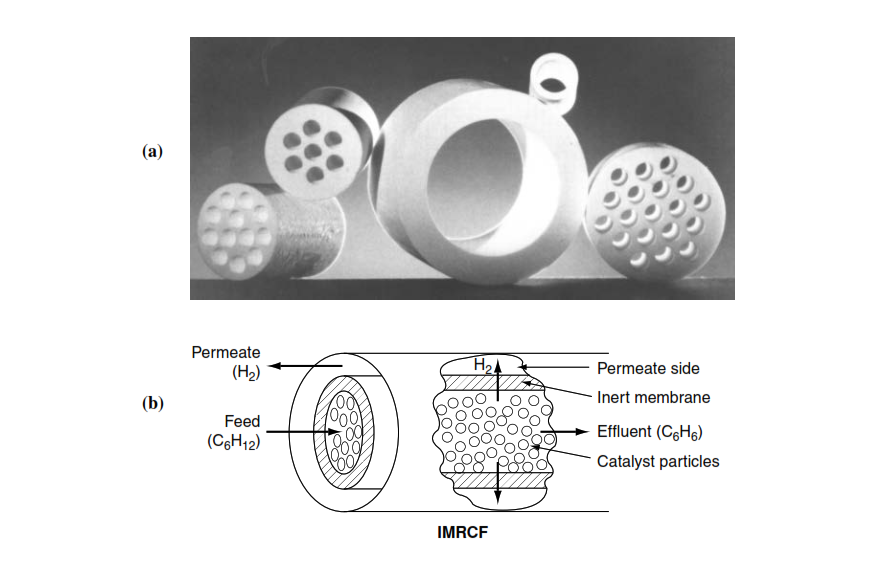

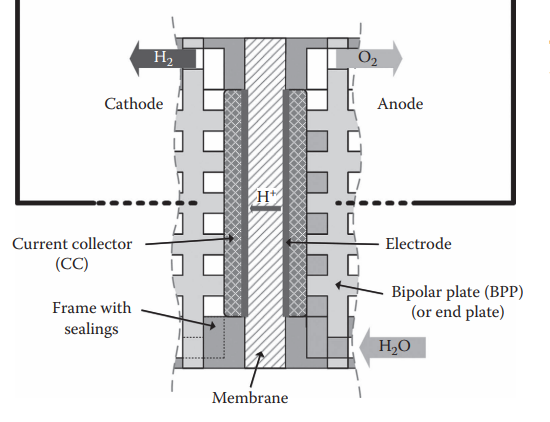

clear all
syms n F Ae i Na(x) At Nb(x) Nc(x) Neod Nd  R 
T=298.15

T = 298.1500

n=4

n = 4

F=9600

F = 9600

Ae=500

Ae = 500

At=700

At = 700

I=30

I = 30

i=I/Ae;
nd=0.016*T-2.89556;
Neod=(nd*i*18*Ae)/F

Neod = 0.1055

Nd=2

Nd = 2


r= I/(n*F)

r = 7.8125e-04

eqA=diff(Na,x)==-Neod-Nd

$$eqA(x) = \frac{\partial }{\partial x}\mathrm{Na}\left(x\right)=-\frac{4741073872771789}{2251799813685248}$$

eqB=diff(Nb,x)==r*At

$$eqB(x) = \frac{\partial }{\partial x}\mathrm{Nb}\left(x\right)=\frac{35}{64}$$

eqC=diff(Nc,x)==1/2*r*At

$$eqC(x) = \frac{\partial }{\partial x}\mathrm{Nc}\left(x\right)=\frac{35}{128}$$

Pa=Na*R*T/At*x

$$Pa(x) = \frac{5963\,R\,x\,\mathrm{Na}\left(x\right)}{14000}$$


SE=[eqA;eqB;eqC]

$$SE(x) = \left(\begin{array}{c} \frac{\partial }{\partial x}\mathrm{Na}\left(x\right)=-\frac{4741073872771789}{2251799813685248}\\ \frac{\partial }{\partial x}\mathrm{Nb}\left(x\right)=\frac{35}{64}\\ \frac{\partial }{\partial x}\mathrm{Nc}\left(x\right)=\frac{35}{128} \end{array}\right)$$

[V,S]= odeToVectorField(SE)

$$V = \left(\begin{array}{c} \frac{35}{64}\\ -\frac{4741073872771789}{2251799813685248}\\ \frac{35}{128} \end{array}\right)$$

$$S = \left(\begin{array}{c} \mathrm{Nb}\\ \mathrm{Na}\\ \mathrm{Nc} \end{array}\right)$$

M = matlabFunction(V,'vars',{'x','Y'})

M = function_handle with value:
    @(x,Y)[3.5e+1./6.4e+1;-2.10545975;3.5e+1./1.28e+2]


interval = [1e-10 20];

 yInit = [0 100 0];
 ySol = ode23(M,interval,yInit)

ySol = struct with fields:
     solver: 'ode23'
    extdata: [1×1 struct]
          x: [1.0000e-10 1.4629e-04 8.7771e-04 0.0045 0.0228 0.1142 0.5714 2.5714 4.5714 6.5714 8.5714 10.5714 12.5714 14.5714 16.5714 18.5714 20]
          y: [3×17 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


 ySol.y(1,:)

ans =          0    0.0001    0.0005    0.0025    0.0125    0.0625    0.3125    1.4062    2.5000    3.5937    4.6875    5.7812    6.8750    7.9687    9.0625   10.1562   10.9375



    ySol.y(1,end)+ySol.y(2,end)+ySol.y(3,end)

ans = 74.2971